# Allan Variance

    Gabriel Nunes

Let's consider a data collection of $N$ samples with fixed sample period $\tau_0$. We will form data clusters of different time durations:

$\tau_0 ,{2\tau }_0 ,\cdots ,m\tau_0$.

Being $m<(N-1)/2$.

Then, calculate an array with the average of each cluster. For higher values of $N$ the overlapping method is more significant.

The Allan deviance is defined by: 

$\sigma \left(\tau \right)=\frac{1}{2\tau^2 }\langle {\left(\theta_{k+2m} -2\theta_{k+m} +\theta_k \right)}^2 \rangle$.

Being $\tau=m\tau_0$. The average can be expanded as

$\sigma \left(\tau ,m\right)=\frac{1}{2\tau^2 \left(N-2m\right)}\sum_{k=1}^{N-2m} {\left(\theta_{k+2m} -2\theta_{k+m} +\theta_k \right)}^2$.

$m$ is an array of unique integers, from 0 to $m_{max}$

**Importing the data file:**

% cd('D:\Users\Stinky\MATLAB Drive\IEAv PC\Allan Variance')
% file = 'GiroData_24hrs.txt';
file = 'GiroData_03052022_1250.txt';
tic
gyro = readmatrix(file);
toc

Elapsed time is 10.055152 seconds.



file = 'Accelerometer_Allan_10Hz_labview_Tfake.txt';
tic
fid = fopen(file,'r');
acc = fscanf(fid,'%f');
toc

Elapsed time is 0.628791 seconds.


fclose(fid);
acc = acc(1:2:end);


## Allan variance based on freescale application note

### Gyroscope

clearvars -except gyro acc

omega = gyro(1.35e6:4.86e6,1);  % Angular velocity
fs = 100;                       % Sample rate
pts = 1000;                      % Number of Allan variance points 
t_gyro = linspace(0,(length(omega)-1)/fs,length(omega));


#### Temporal data

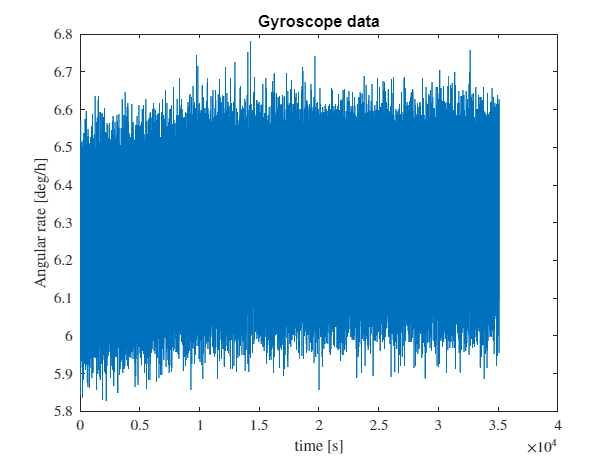

figure()
plot(t_gyro, omega)
    title('Gyroscope data')
        xlabel('time [s]','interpreter','latex')
        ylabel('Angular rate [deg/h]','interpreter','latex')

#### Allan deviation

[taus_gyro_1, avar_gyro_1] = calc_avar(omega,fs,pts);

Elapsed time is 33.559572 seconds.


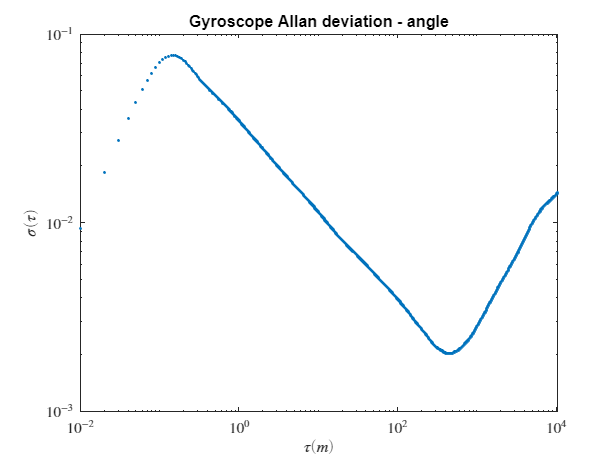


figure()
loglog(taus_gyro_1,sqrt(avar_gyro_1),'.')
    title('Gyroscope Allan deviation - angle')
    xlabel('$\tau(m)$','interpreter','latex')
    ylabel('$\sigma(\tau)$','interpreter','latex')    

### Accelerometer

accel = acc(:,1);           % Acceleration data
fs_acc = 10;                % Sample rate
pts = 1000;                  % Number of output points
t_acc = linspace(0,(length(accel)-1)/fs_acc,length(accel));

#### Temporal data

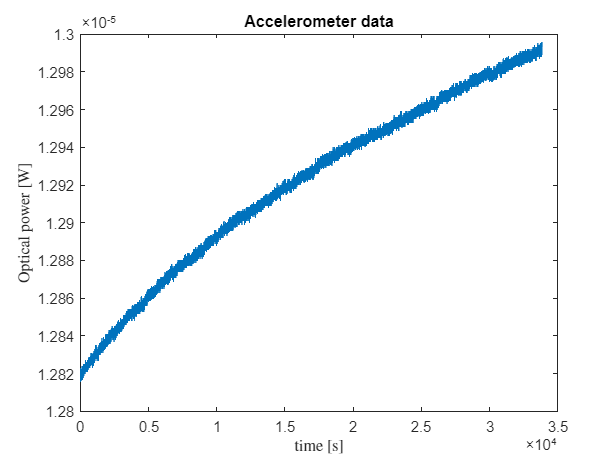

figure()
plot(t_acc, accel)
    title('Accelerometer data')
    xlabel('time [s]','interpreter','latex')
    ylabel('Optical power [W]','interpreter','latex')    

#### Allan deviation

[taus_acc_1, avar_acc_1] = calc_avar(accel,fs_acc,pts);

Elapsed time is 2.291633 seconds.


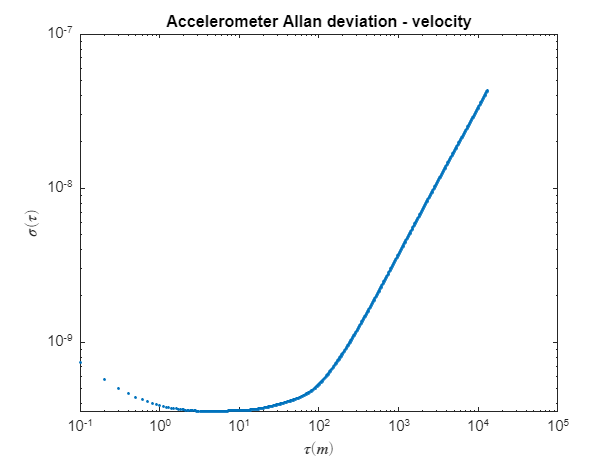

figure
loglog(taus_acc_1, sqrt(avar_acc_1),'.')
    title('Accelerometer Allan deviation - velocity')
    xlabel('$\tau(m)$','interpreter','latex')
    ylabel('$\sigma(\tau)$','interpreter','latex')

## Allan variance from MATLAB

There is a command in matlab that calculate the Allan variance (allanvar). The syntax is as follows:

`Where `$m$ is an array of cluster sizes that we will use to calculate the Allan variance.

#### Gyroscope

pts = 1e3; 
m_max = (length(omega)-1)/2;
m_max = 2.^(floor(log2(m_max)));
m = logspace(0, log10(m_max), pts)';
m = ceil(m);
m = unique(m);

tic
[avar_gyro_2, taus_gyro_2] = allanvar(omega,m,fs);
toc

Elapsed time is 5.719670 seconds.


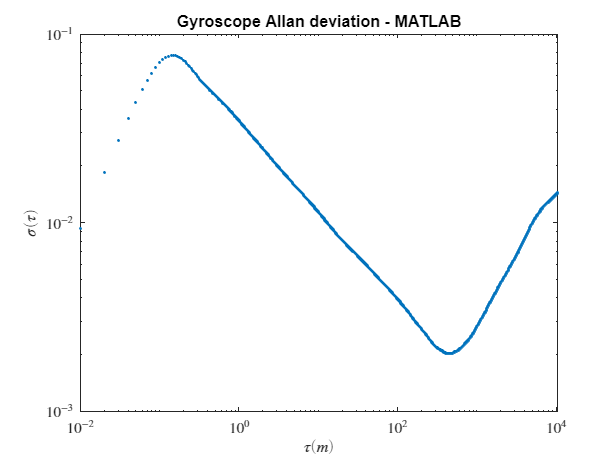

figure
loglog(taus_gyro_2, sqrt(avar_gyro_2),'.')
    title('Gyroscope Allan deviation - MATLAB')
    xlabel('$\tau(m)$','interpreter','latex')
    ylabel('$\sigma(\tau)$','interpreter','latex')

#### Accelerometer

pts = 1e3; 
m_max = (length(accel)-1)/2;
m_max = 2.^(floor(log2(m_max)));
m = logspace(0, log10(m_max), pts)';
m = ceil(m);
m = unique(m);

tic
[avar_accel_2, taus_accel_2] = allanvar(accel,m,fs);
toc

Elapsed time is 0.315393 seconds.


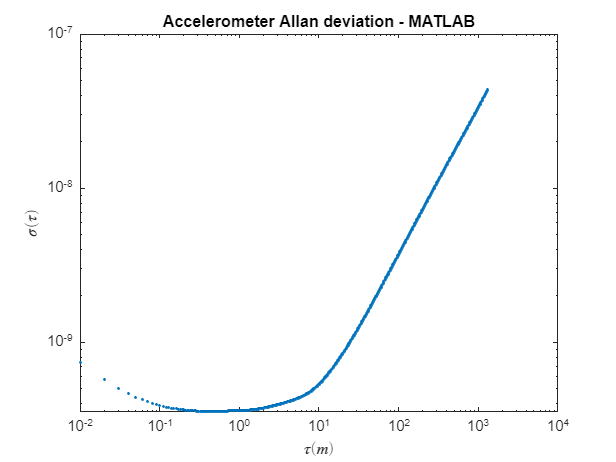


figure
loglog(taus_accel_2, sqrt(avar_accel_2),'.')
    title('Accelerometer Allan deviation - MATLAB')
    xlabel('$\tau(m)$','interpreter','latex')
    ylabel('$\sigma(\tau)$','interpreter','latex')    

### Script by Brian Douglas

% [taus_bd, avar_bd] = allan_briandouglas(omega,100);
% figure()
% loglog(taus_bd, avar_bd)

**Comparing different algorithms**

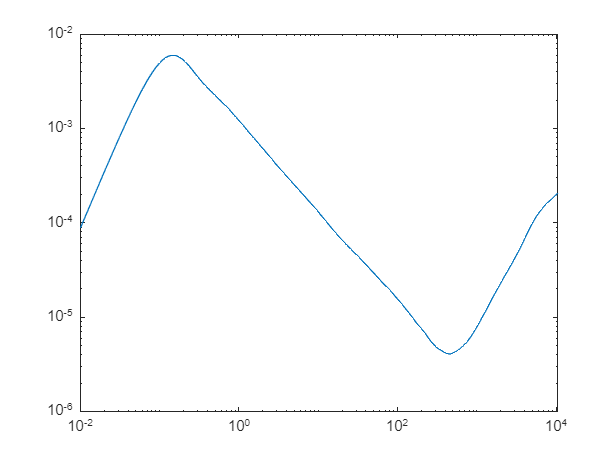

figure

loglog(taus_gyro_1, avar_gyro_1)

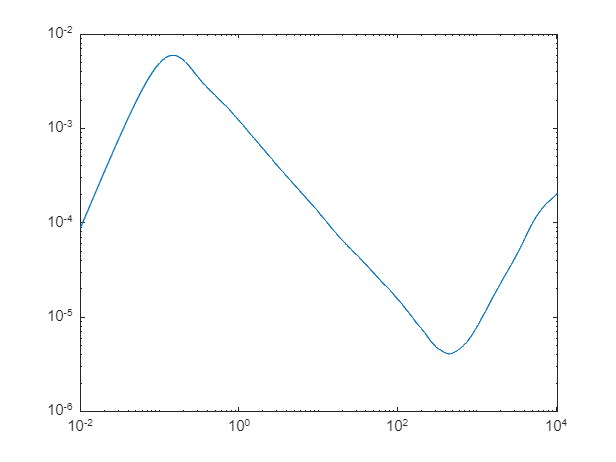

loglog(taus_gyro_2, avar_gyro_2)

% loglog(taus_bd, avar_bd)

function [taus, avar] = calc_avar(omega,fs,pts)
    N = length(omega);
    theta = cumsum(omega)/fs;
    max_m = 2^floor(log2(N/2)); % Max m in defined by power of 2
    m = logspace(0, log10(max_m), pts)'; % why array of m?
    m = ceil(m);        
    m = unique(m);
    
    tau0 = 1/fs;
    taus = m*tau0;      % Cluster durations
    
    avar = zeros(length(m), 1);
    % Half vectorized approach
    tic
    for k = 1:length(m)
        avar(k) = sum( (theta(k+2*m(k):N) - 2*theta(k+m(k):N-m(k)) + theta(k:N-2*m(k))).^2 );
    end
    avar = avar./(2.*taus.^2 .* (N-2*m));
    toc
end

function [taus, avar] = allan_briandouglas(data,fs)
% Script by Brian Douglas
% https://www.youtube.com/watch?v=P1OEoA70YJo
    tic
	N = length(data);
	time = linspace(0,(N-1)/fs,N);
    
    d = 9;%2000;% divided by more than 9 will reduce the meaningness of the averaging
	numtaus = floor(length(data)/d); 
	for b = 1:floor(numtaus)
		taus(b) = time(b+1)-time(1);
	end

	for h = 1:numtaus
		binvar = 0;
		avebin = 0;
		totalbins = floor(time(length(time))/taus(h));
		lengthbins = floor(length(time)/totalbins);

		for j = 1:totalbins
			avebin(j)=mean(data( lengthbins*(j-1) + 1:lengthbins*j ));
		end

		for j = 1:(totalbins-1)
			binvar(j)=(avebin(j+1)-avebin(j))^2; % Allan variance
		end

		avar(h) = sum(binvar)/(2*(totalbins-1));
	end
    toc
end